# IRS Power Allocation For UP Link

clear; clc; close all;

## Initializations:

- *Pk *represents the corresponding transmit power, satisfying  *P**k **≤ **P**k*max, with *P**k*max being the maximum transmit power.

- **h***k **2 *C*N**×*1 denotes the channel vector between user  *k *and IRS, while **h**BS *2 *C*N**×*1 represents that between the IRS and BS.  

- $\Phi$ is a diagonal matrix accounting for the effective phase shifts from all IRS reflecting elements  


K = 3; % Num of Users
Sigma = 1; % Noise Variation

N = 5; % Number of Channels between user k and the IRS (intelligent reflecting surface) and Also between IRS and the Base Station (BS)



PHI = (diag(randn(1,N)+1j*randn(1,N)));

PHI = diag( diag(PHI./abs(PHI)) )  ; % Normalise PHI --> abs(PHI) = 1 ;
P_k_max = 10; % Maximum Transmit Power for each user
Pk_Max = randi(10,K,1);
Total_power = 11;

h    = randn(N,K) + 1j*randn(N,K) ;  % Complex Vectors  -- > Between user k and the IRS
h_BS = randn(N,1) + 1j*randn(N,1) ;  % Complex Vectors  -- > Between IRS and the BS

Rk_min = 0.05*randi(5,1,K) ; % Rkmin = 0:05 bps/Hz

## CVX


cvx_begin 
    variables P(K,1)
            SUM_K_H  =  abs(conj(h_BS')*PHI*h).^2;
            SUM_K_H_P  =  SUM_K_H*P;

            maximize( log( 1 + SUM_K_H_P/Sigma^2  )/log(2)   ); % Maximize the Quality of Service which the Throughput of the channel
                subject to
                    ones(1,K)*P == Total_power; 
                    P <= Pk_Max;
                    for k=1:K-1
                         temp = abs(conj(h_BS')*PHI*h).^2;
                         P(k,1) >= (2^Rk_min(1,k)  - 1)*(  temp(1,k+1:end) *P(k+1:end,1)  + Sigma^2  )/ SUM_K_H(1,k)  ;

                    end

cvx_end

 
Successive approximation method to be employed.
   For improved efficiency, SDPT3 is solving the dual problem.
   SDPT3 will be called several times to refine the solution.
   Original size: 8 variables, 3 equality constraints
   1 exponentials add 8 variables, 5 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
  1/  1 | 3.096e+00  1.055e+00  0.000e+00 | Solved
  1/  1 | 8.019e-01  5.476e-02  0.000e+00 | Solved
  1/  1 | 3.378e-02  9.084e-05  0.000e+00 | Solved
  0/  1 | 4.197e-04  8.731e-09  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): +7.11372
 


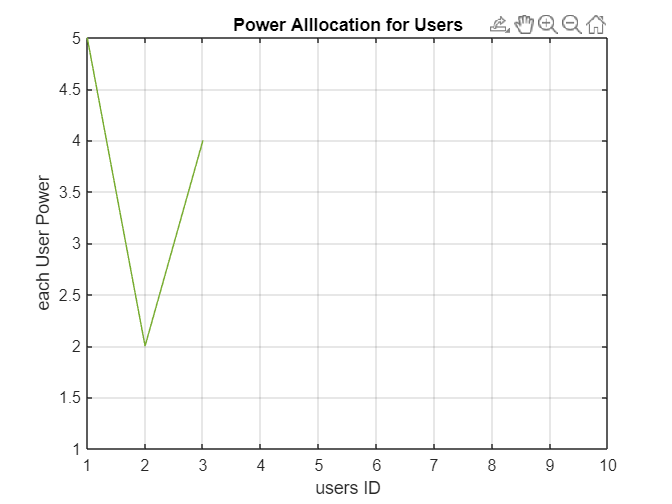

figure(1)
plot(P)
hold on
plot(P_k_max,ones(1,length(P)))
grid on
title("Power Alllocation for Users")
xlabel("users ID")
ylabel("each User Power")

figure(2)

cvx_slvtol = 4.3074e-09

subplot(2,2,1)

cvx_status = 'Solved'

plot()

cvx_optval = 7.1137

cvx_slvitr = 44

cvx_optbnd = 7.1137

cvx_cputime = 3.6719

cvx_slvtol
cvx_status
cvx_optval
cvx_slvitr
cvx_optbnd
cvx_cputime




